test = imread('test.png');
file = load("colormap7.mat");
rgb = file.rgb;
siz = size(test);
matrix = zeros(siz(1),siz(2),"int16");
for i = 1:siz(1)
    for j = 1:siz(2)
        a = test(i,j,1)+1;
        b = test(i,j,2)+1;
        c = test(i,j,3)+1;
        matrix(i,j) = rgb(a,b,c);
    end
end

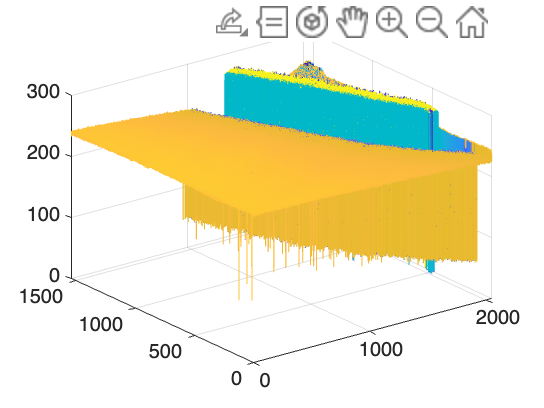

mesh(matrix);

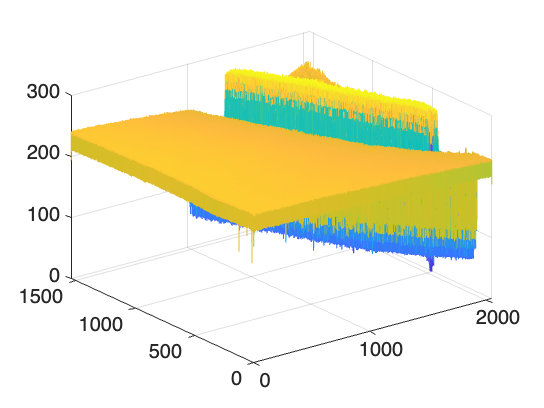

% view(45,30)
h =fspecial('gaussian');
ma = filter2(h,matrix);
mesh(ma)

% view(45,30)